# Problem 1

k = 4

k = 4

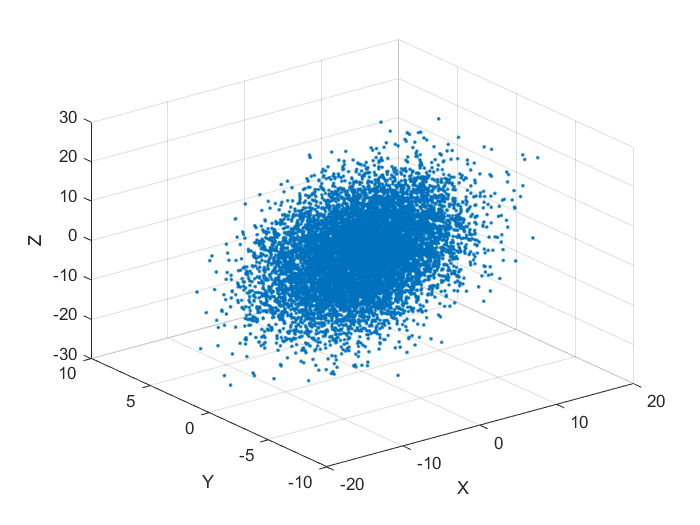

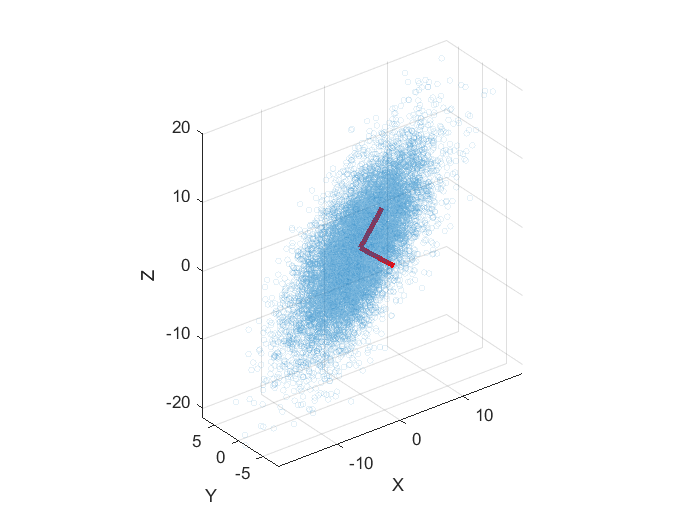

N = 1e4;

rng(10);
X = normrnd(0, k + 1, N, 1);
Y = normrnd(0, sqrt(k + 1), N, 1);
epsilon = normrnd(0, 1, N, 1);
Z = X + Y + epsilon;

P = [X, Y, Z];

figure
scatter3(X, Y, Z, '.');
xlabel('X'); ylabel('Y'); zlabel('Z');

q = 1 : 10;
% q = unique(floor(logspace(0, 1, 10)));
n = 1000*q;

V_set_1 = zeros(3, length(n));
V_set_2 = zeros(3, length(n));

figure(2);
for i = 1 : length(n)
    Pi = P(1:n(i), :);
    A = Pi.' * Pi;
    [V, lam] = eig(A);
    [lam, ind] = sort(diag(lam), 'descend');
    V = V(:, ind);
    V_set_1(:, i) = V(:, 1);
    V_set_2(:, i) = V(:, 2);
    
    scatter3(P(1:n(i), 1), P(1:n(i), 2), P(1:n(i), 3), 12, 'o', 'MarkerEdgeAlpha', .1);
    axis equal;
    xlabel('X'); ylabel('Y'); zlabel('Z');
    for j = 1 : 2
        line([0 log10(lam(j))*V(1, j)], [0 log10(lam(j))*V(2, j)], [0 log10(lam(j))*V(3, j)], ...
            'color', 'red', 'LineWidth', 3);
    end
    drawnow
end

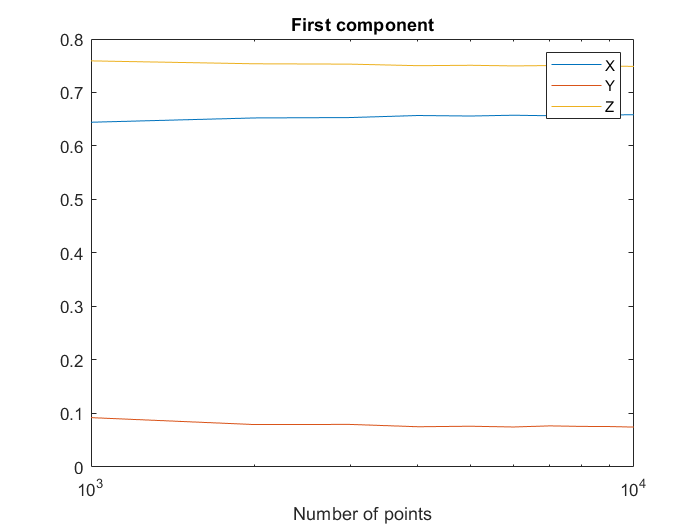


figure(3)
semilogx(n, V_set_1);
legend('X', 'Y', 'Z');
xlabel('Number of points');
title('First component');

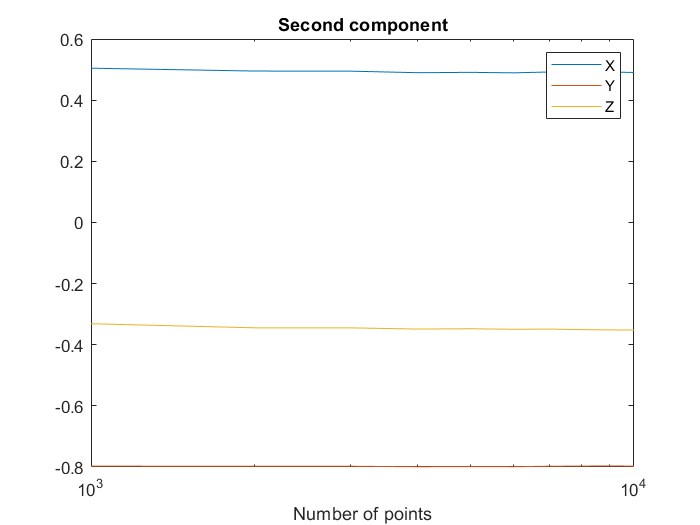


figure(4)
semilogx(n, V_set_2);
legend('X', 'Y', 'Z');
xlabel('Number of points');
title('Second component');

# Problem 2

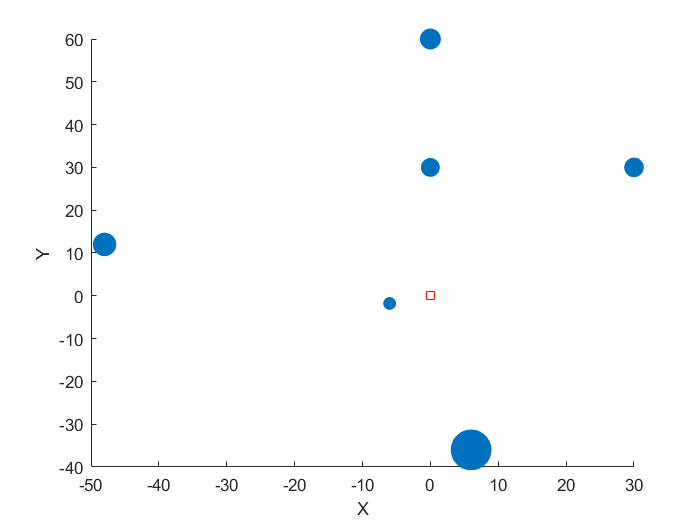

k = 6;
z = [0, 10*k;
    5*k, 5*k;
    0, 5*k;
    -8*k, 2*k;
    -k, -log(k);
    k, -k^2];
T = [10+k, 8+k, 1+2*k, 20, k, 10*k];

figure
scatter(z(:, 1), z(:, 2), 10*T, 'o', 'filled');
hold on;
scatter(0, 0, 'square', 'red')
hold off;
xlabel('X'); ylabel('Y');


K_fun = @(z1, z2) exp(-norm(z1 - z2)^2/(10*k^2));

Q = zeros(size(z, 1));
B = zeros(size(z, 1), 1);
for i = 1 : size(z, 1)
    for j = 1 : size(z, 1)
        Q(i, j) = K_fun(z(i, :), z(j, :));
    end
    B(i) = K_fun(z(i, :), [0 0]);
end

A = linsolve(Q, B);

T_0 = T * A;
disp(['Interpolated termperature: ' num2str(T_0), '°C']);

Interpolated termperature: 5.8257°C


# Problem 3

coeffs = compact_wave_coeffs()

$$coeffs = \begin{array}{l} \left(\begin{array}{c} -\frac{\nu^{2}-1}{2\,\left(\nu^{2}+5\right)}\\ \frac{10\,\nu^{2}-10}{\nu^{2}+5}\\ -\frac{5\,\nu^{2}+1}{\nu^{2}+5}\\ \frac{25\,\tau^{2}}{6\,\left(\nu^{2}+5\right)}\\ \sigma_{1}\\ \sigma_{1}\\ \frac{\tau^{2}}{24\,\left(\nu^{2}+5\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{5\,\tau^{2}}{12\,\left(\nu^{2}+5\right)} \end{array}$$

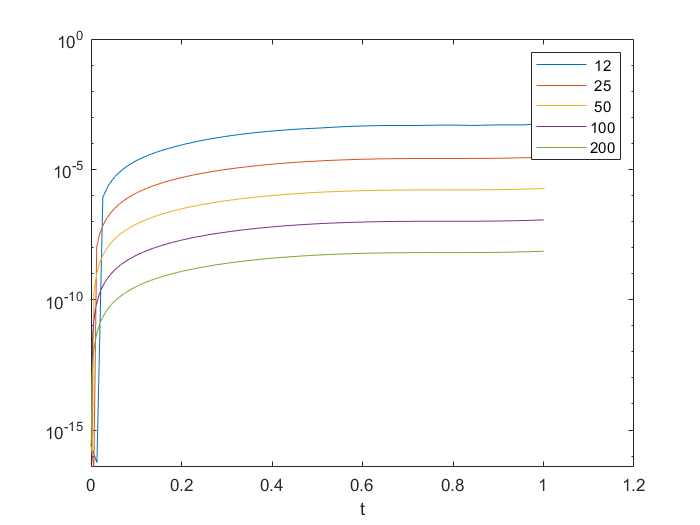

k = 4;
%% Main parameters
C = k;
L = 2*pi;
T = 1;

Nx = [12, 25, 50, 100, 200].';
nu = .1; % nu = C * tau / h

u_0 = @(x) sin(x);
u_tau = @(x, tau) sin(x + k*tau);
u_ref = @(x, t) sin(x + k*t);

C_norm = zeros(length(Nx), 1);
figure
for i = 1 : length(Nx)
    x = linspace(0, L, Nx(i) + 1);
    [U, T_fin, tau] = wave_integration(T, C, L, Nx(i), nu, u_0, u_tau);
    t = 0 : tau : T_fin;
    [x_mesh, t_mesh] = meshgrid(x, t);
    C_norm_t = max(abs(U - u_ref(x_mesh, t_mesh)), [], 2);
    C_norm(i) = C_norm_t(end);
    semilogy(t, C_norm_t); hold on;
end
hold off;
xlabel('t');
legend(num2str(Nx));

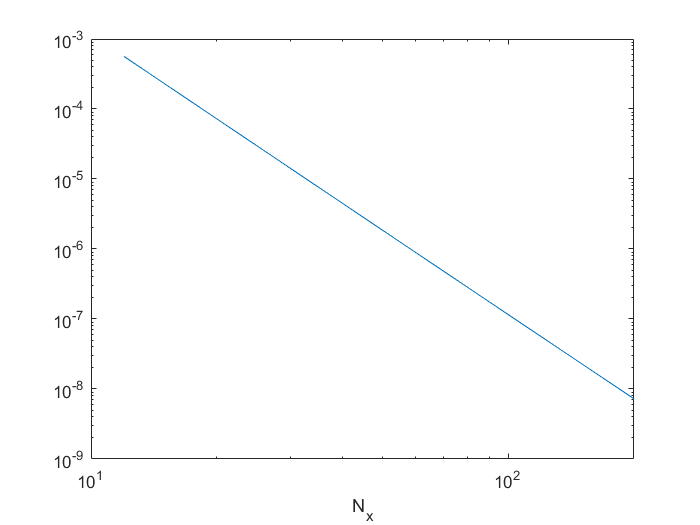


figure
loglog(Nx, C_norm);
xlabel('N_x');

order = (log10(C_norm(end)) - log10(C_norm(1))) / ...
    (log10(Nx(end)) - log10(Nx(1)));
disp(['Order of the compact scheme: ' num2str(-order)]);

Order of the compact scheme: 4.0026
